# **Implementation of the Partial Least Squares (PLS) algorithm for classification**

Runnable example of how *PLS.m*, i.e. the class that implements the Partial Least Squares algorithm, can be use to perform fault diagnosis. In particular, the example in this script deals with steel plates: starting from $27$ variables, we want to train a PLS models (simplified thanks to the *order reduction*) that it is able to predict the fault classes.

#### 1. Data import

clc
clearvars
warning off

data = readtable("..\Data\Sources\stell-faults.csv");
faultClasses = data.Properties.VariableNames;
faultClasses = faultClasses(28:end);
rowLimits = [158 348 739 811 866 1268 size(data, 1)];
colLimits = 28:size(data, 2);

#### 2. Preliminary analysis: choice of *p *through test CV MCE

nIter = 10;
for nVar = 2:length(faultClasses)
    disp("p = " + nVar)
    subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
    X = subset{1:rowLimits(nVar), 1:28};
    Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};
    mhat = PLS(X, Y, true, true, 1000, 1e-10, false);
    mhat = mhat.orderAnalysis(nIter, false);
    if nVar == 2
        figure
        plot(mhat.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
        xlim([0 size(X, 2)+1])
    else
        hold on
        grid on
        plot(mhat.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
    end
end

p = 2
p = 3
p = 4
p = 5
p = 6
p = 7


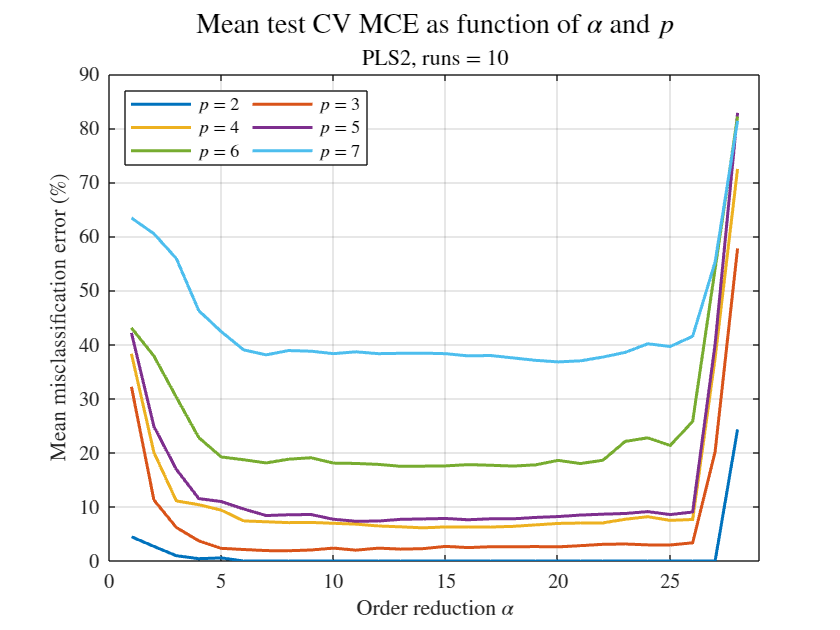

xlabel("Order reduction $\alpha$", 'Interpreter', 'latex');
ylabel("Mean misclassification error (\%)", 'Interpreter', 'latex');
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
leg = repmat("$p$ = ", 1, length(faultClasses)-1) + (2:length(faultClasses));
legend(leg, 'Interpreter', 'latex', 'Orientation', 'horizontal',...
    'Location', 'northwest', 'NumColumns', 2)
title("Mean test CV MCE as function of $\alpha$ and $p$", 'FontSize', 14, 'Interpreter', 'latex')
subtitle("PLS2, runs = " + nIter, 'Interpreter', 'latex')

#### 3. Identification of the best order reduction through test CV MCE

runs = 50;

% PLS2
model2 = PLS(X, Y, true);

PLS configuration: 
- PLS2: true
- Standardization: true
- Maximum iterations: 10000
- Tolerance: 1e-10
- Default order reduction: 28


model2 = model2.orderAnalysis(runs);

PLS order reduction analysis:
- Run 1 of 50, order 1 of 28 (0.07%)
- Run 1 of 50, order 2 of 28 (0.14%)
- Run 1 of 50, order 3 of 28 (0.21%)
- Run 1 of 50, order 4 of 28 (0.29%)
- Run 1 of 50, order 5 of 28 (0.36%)
- Run 1 of 50, order 6 of 28 (0.43%)
- Run 1 of 50, order 7 of 28 (0.5%)
- Run 1 of 50, order 8 of 28 (0.57%)
- Run 1 of 50, order 9 of 28 (0.64%)
- Run 1 of 50, order 10 of 28 (0.71%)
- Run 1 of 50, order 11 of 28 (0.79%)
- Run 1 of 50, order 12 of 28 (0.86%)
- Run 1 of 50, order 13 of 28 (0.93%)
- Run 1 of 50, order 14 of 28 (1%)
- Run 1 of 50, order 15 of 28 (1.07%)
- Run 1 of 50, order 16 of 28 (1.14%)
- Run 1 of 50, order 17 of 28 (1.21%)
- Run 1 of 50, order 18 of 28 (1.29%)
- Run 1 of 50, order 19 of 28 (1.36%)
- Run 1 of 50, order 20 of 28 (1.43%)
- Run 1 of 50, order 21 of 28 (1.5%)
- Run 1 of 50, order 22 of 28 (1.57%)
- Run 1 of 50, order 23 of 28 (1.64%)
- Run 1 of 50, order 24 of 28 (1.71%)
- Run 1 of 50, order 25 of 28 (1.79%)
- Run 1 of 50, order 26 of 28 (1.8

% PLS1
model1 = PLS(X, Y, false);

PLS configuration: 
- PLS2: false
- Standardization: true
- Maximum iterations: 10000
- Tolerance: 1e-10
- Default order reduction: 28


model1 = model1.orderAnalysis(runs);

PLS order reduction analysis:
- Run 1 of 50, order 1 of 28 (0.07%)
- Run 1 of 50, order 2 of 28 (0.14%)
- Run 1 of 50, order 3 of 28 (0.21%)
- Run 1 of 50, order 4 of 28 (0.29%)
- Run 1 of 50, order 5 of 28 (0.36%)
- Run 1 of 50, order 6 of 28 (0.43%)
- Run 1 of 50, order 7 of 28 (0.5%)
- Run 1 of 50, order 8 of 28 (0.57%)
- Run 1 of 50, order 9 of 28 (0.64%)
- Run 1 of 50, order 10 of 28 (0.71%)
- Run 1 of 50, order 11 of 28 (0.79%)
- Run 1 of 50, order 12 of 28 (0.86%)
- Run 1 of 50, order 13 of 28 (0.93%)
- Run 1 of 50, order 14 of 28 (1%)
- Run 1 of 50, order 15 of 28 (1.07%)
- Run 1 of 50, order 16 of 28 (1.14%)
- Run 1 of 50, order 17 of 28 (1.21%)
- Run 1 of 50, order 18 of 28 (1.29%)
- Run 1 of 50, order 19 of 28 (1.36%)
- Run 1 of 50, order 20 of 28 (1.43%)
- Run 1 of 50, order 21 of 28 (1.5%)
- Run 1 of 50, order 22 of 28 (1.57%)
- Run 1 of 50, order 23 of 28 (1.64%)
- Run 1 of 50, order 24 of 28 (1.71%)
- Run 1 of 50, order 25 of 28 (1.79%)
- Run 1 of 50, order 26 of 28 (1.8

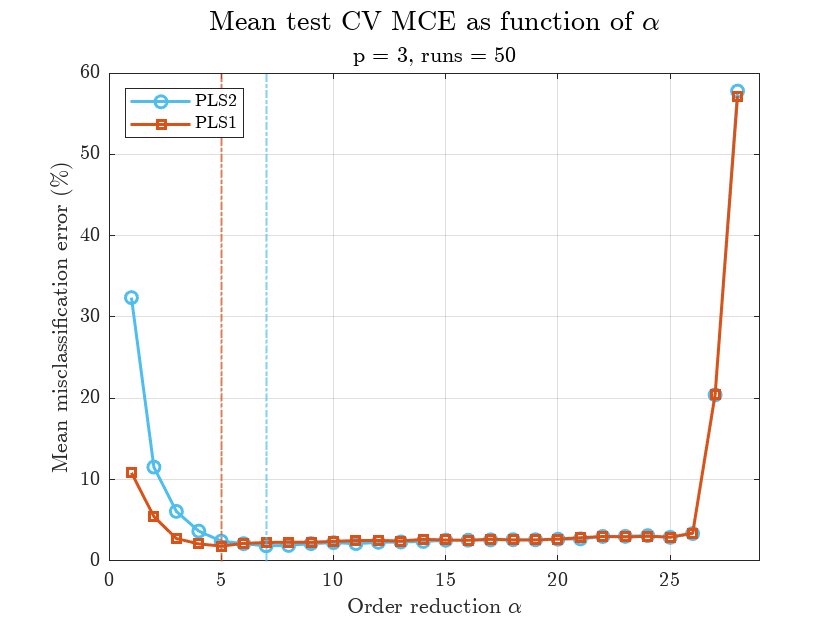

% results plotting
figure
plot(model2.orderRed.MCE_statistics.Avg*100, '-o', 'LineWidth', 1.5, 'Color', '#4DBEEE')
xlim([0 model2.mX+1])
hold on
grid on
plot(model1.orderRed.MCE_statistics.Avg*100, '-square', 'LineWidth', 1.5, 'Color', '#D95319')
xline(model2.orderRed.bestAlpha, '-.', 'Color', '#4DBEEE', 'LineWidth', 1)
xline(model1.orderRed.bestAlpha, '-.', 'Color', '#D95319', 'LineWidth', 1)
xlabel('Order reduction $\alpha$', 'Interpreter', "latex")
ylabel('Mean misclassification error (\%)', 'Interpreter', 'latex')
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
legend("PLS2", "PLS1", 'Interpreter', 'latex', 'location', 'northwest');
title("Mean test CV MCE as function of $\alpha$", 'Interpreter', 'latex', ...
    'FontSize', 14)
subtitle("$p$ = " + nVar + ", runs = " + runs, 'Interpreter', 'latex')

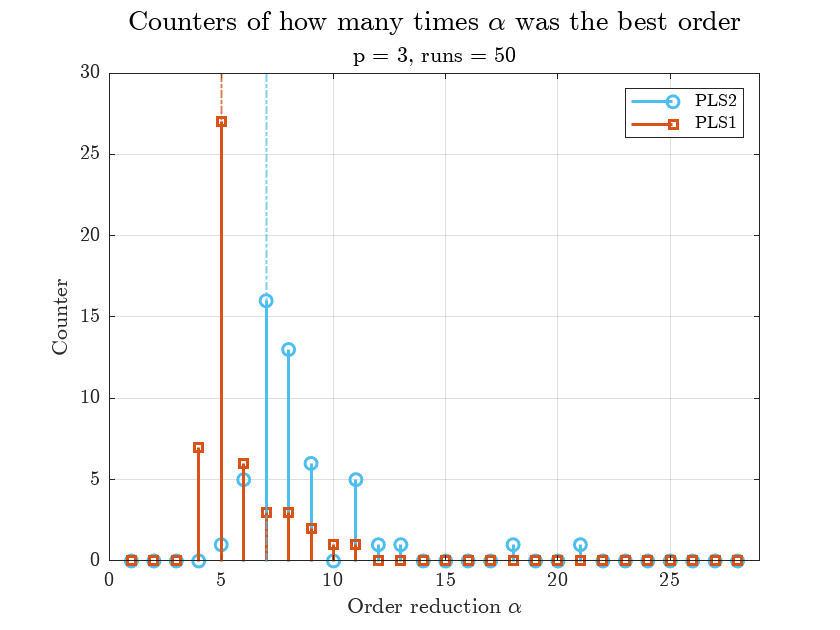

figure
stem(model2.orderRed.bestAlphaCounters.Counter, 'o', 'LineWidth', 1.5, 'Color', '#4DBEEE')
xlim([0 model2.mX+1])
hold on
grid on
stem(model1.orderRed.bestAlphaCounters.Counter, 'square', 'LineWidth', 1.5, 'Color', '#D95319')
xline(model2.orderRed.bestAlpha, '-.', 'Color', '#4DBEEE', 'LineWidth', 1)
xline(model1.orderRed.bestAlpha, '-.', 'Color', '#D95319', 'LineWidth', 1)
xlabel('Order reduction $\alpha$', 'Interpreter', "latex")
ylabel('Counter', 'Interpreter', 'latex')
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
legend("PLS2", "PLS1", 'Interpreter', 'latex', 'location', 'northeast');
title("Counters of how many times $\alpha$ was the best order", 'Interpreter', 'latex', ...
    'FontSize', 14)
subtitle("$p$ = " + nVar + ", runs = " + runs, 'Interpreter', 'latex')

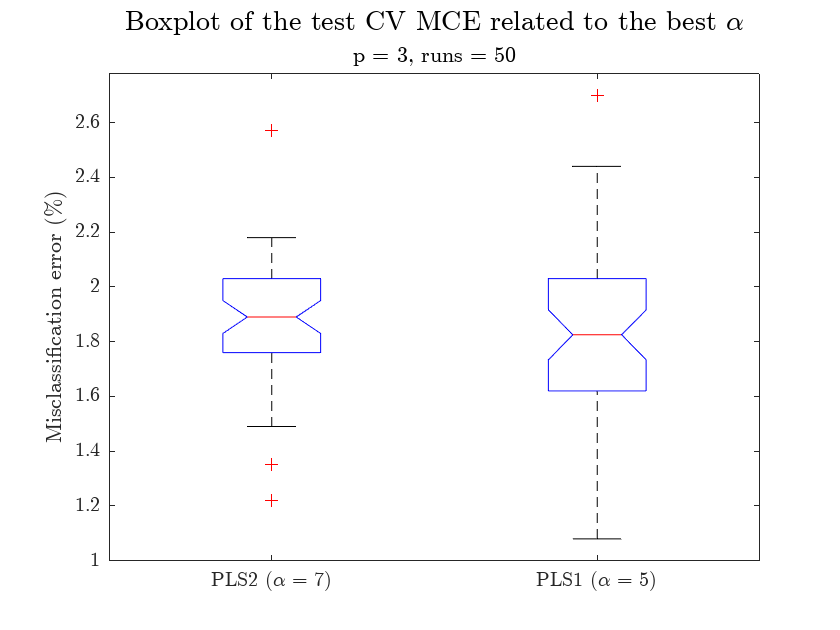

figure
bestAlphaMCE = array2table(zeros(runs, 2));
bestAlphaMCE.Properties.VariableNames = ["PLS2", "PLS1"];
bestAlphaMCE.PLS2 = round(model2.orderRed.alphaMCE{model2.orderRed.bestAlpha, :}*100, 2)';
bestAlphaMCE.PLS1 = round(model1.orderRed.alphaMCE{model1.orderRed.bestAlpha, :}*100, 2)';
boxplot(bestAlphaMCE{:, :}, 'Labels', {'PLS2 ($\alpha$ = 7)', 'PLS1 ($\alpha$ = 5)'},...
    'Notch', 'on')
ylabel('Misclassification error (\%)', 'Interpreter', 'latex')
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
title("Boxplot of the test CV MCE related to the best $\alpha$", 'Interpreter', 'latex',...
    'FontSize', 14)
subtitle("p = " + nVar + ", runs = " + runs, 'Interpreter', 'latex')